### Load de la imatge i conversió a HSL

clear;
close all;
clf;
I = imread('Wally.png');
I_gray = im2gray(I);
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

### Aplicant filtre de mediana

% Extreiem els components R,G,B i els filtrem per separat

% Apliquem filtrat a cada component RGB
Rm1 = medfilt2(R,[1 3]);
Gm1 = medfilt2(G,[1 3]);
Bm1 = medfilt2(B,[1 3]);
% Tornem a composar la imatge original
I(:,:,1) = Rm1; I(:,:,2) = Gm1; I(:,:,3) = Bm1;
% Convertim a espai HSV i extraiem el Hue
HSV = rgb2hsv(I);
Hm = HSV(:,:,1);

### Detecció del groc i del negre

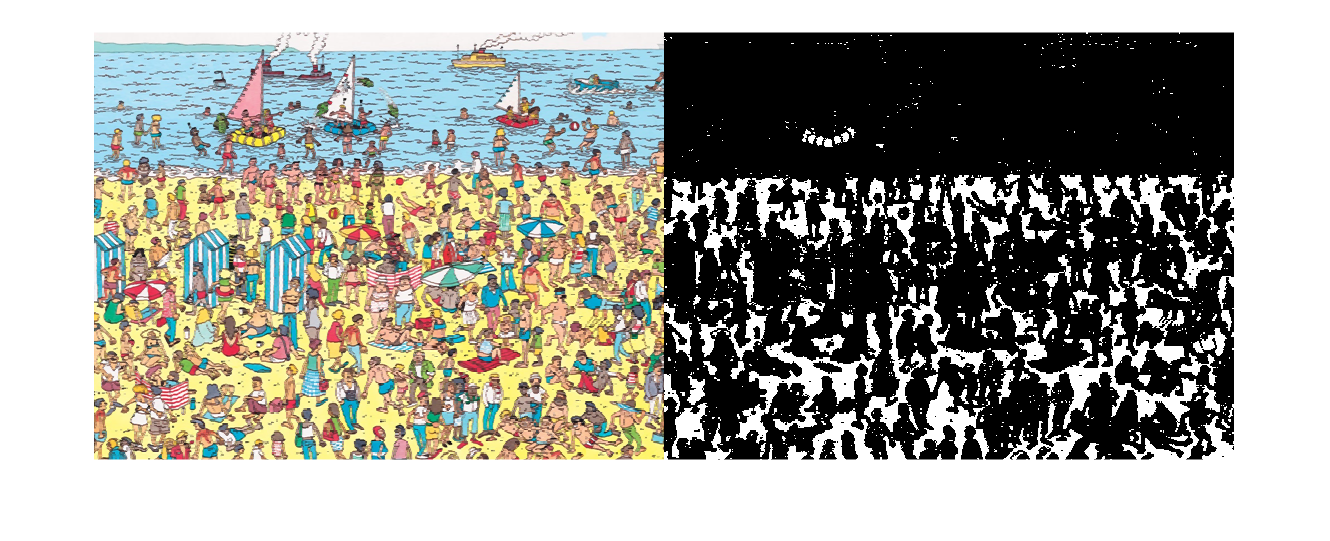

GROC = (Hm >= ((55-5)/360) & Hm <= ((55+5)/360));
imshowpair(I,GROC,'montage');

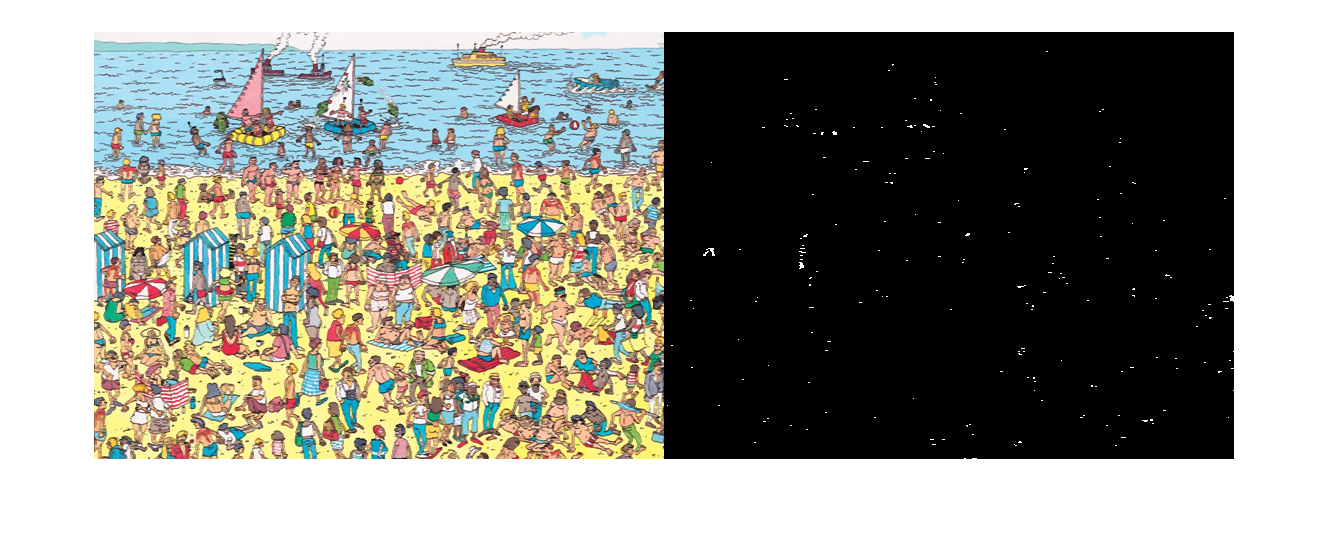

[f,c] = size(Hm);
NEGRE = zeros(f,c);
for i=1:f
    for j=1:c
        NEGRE(i,j) = ((I(i,j,1) < 50) & (I(i,j,2) < 50) & (I(i,j,3) < 50));
    end
end
imshowpair(I,NEGRE,'montage');

### Detecció de línies grogues horitzontals

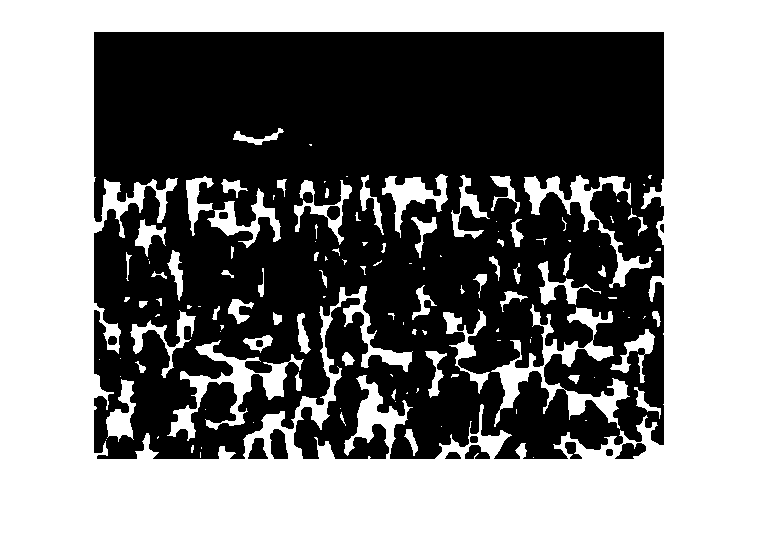

clf;
clear pos;
SE3 = strel('line',3,0);
GROCm = imopen(GROC,SE3);
GROCm = imclose(GROCm,strel('disk',3));
GROCm = imerode(GROCm,strel('disk',1));
imshow(GROCm);

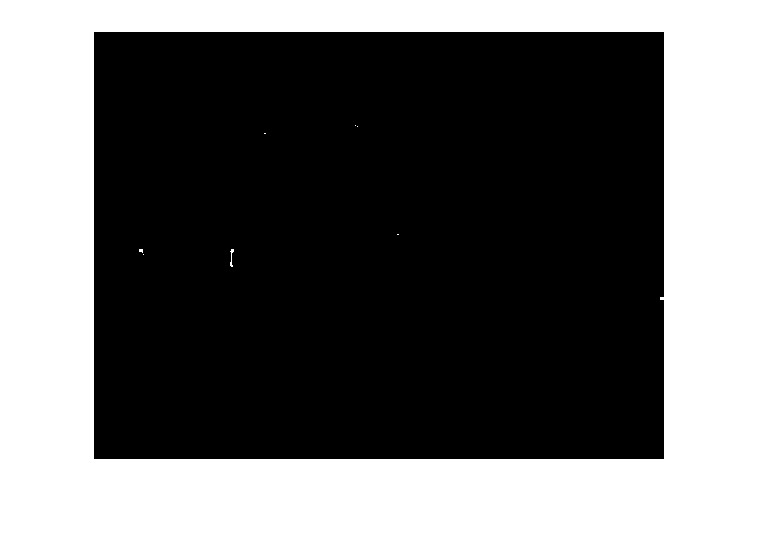


NEGREm = imopen(NEGRE,SE3);
NEGREm = imclose(NEGREm,strel('disk',3));
NEGREm = imerode(NEGREm,strel('disk',1));
imshow(NEGREm);

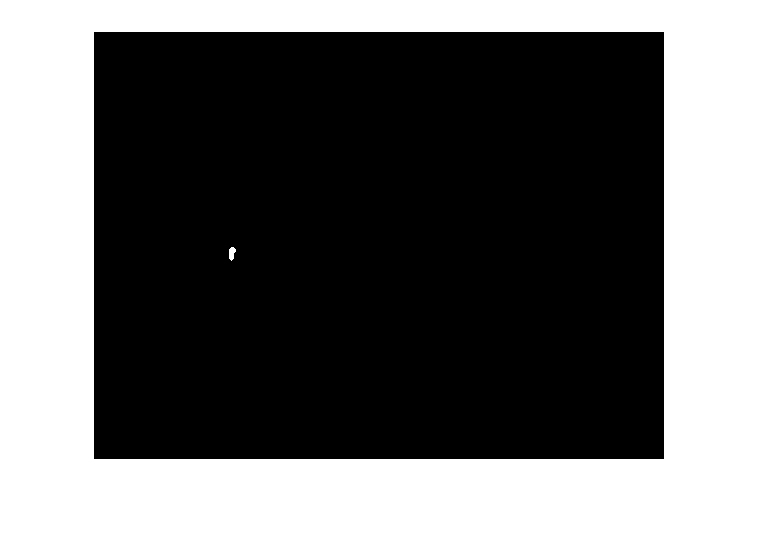



RES = GROCm & NEGREm;
RESm = imdilate(RES,strel('disk',2));
imshow(RESm)

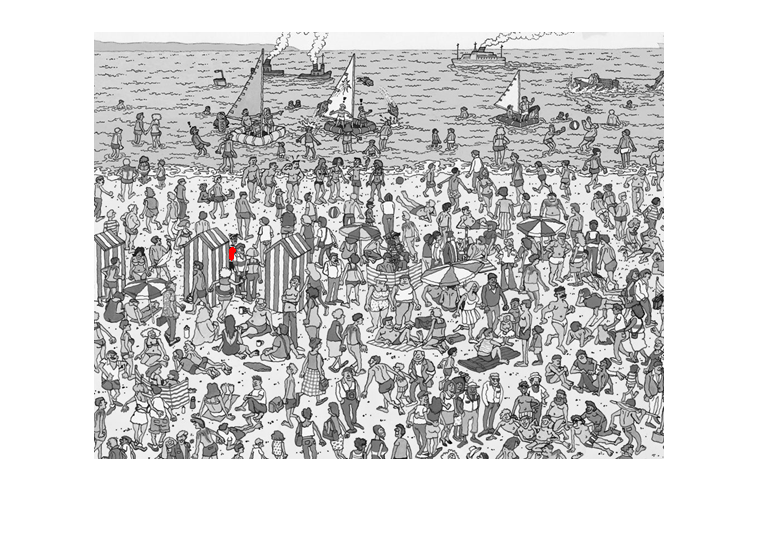

k = 1;
for i=1:f
    for j=1:c
        if RESm(i,j) == 1
            pos(k,1) = j;
            pos(k,2) = i;
            k = k + 1;
        end
    end
end

Result = imoverlay(I_gray, RESm, [1 0 0]);
imshow(Result)